clc;
close all;
clear;
format long;

B = 0.8e9; %带宽
f0 = 9.6e9;
f1 = 10.4e9;
f2 = 10e9; 


f3 = 9.7e9;
f4 = 9.8e9;
f5 = 9.9e9;
f6 = 10e9; 
f7 = 10.1e9;
f8 = 10.2e9;
f9 = 10.3e9;
f10 = 10.4e9;

fs= 40e9;  %采样频率 
Ts=1/fs; %

%采样间隔

T = 20e-6;   %调制时间50us
num = round(T / Ts); %周期采样点数


k = B / T;  %斜率
% t = (0:num-1) / fs; %时间序列
t = 0 : 1/fs : (num-1)/fs;
t1= 0 : 1/fs : (num-1)/fs/2;
t2= num/fs/2 : 1/fs : (num-1)/fs;

t3 = 0 : 1/fs : (num-1)/fs/8;
t4 = (num)/fs/8 : 1/fs : (num-1)/fs/8+(num)/fs/8;
t5 = (num)/fs/4 : 1/fs : (num-1)/fs/8+(num)/fs/4;
t6 = (num)/fs/8*3 : 1/fs : (num-1)/fs/8+(num)/fs/8*3;
t7 = (num)/fs/2 : 1/fs : (num-1)/fs/8+(num)/fs/2;
t8 = (num)/fs/8*5 : 1/fs : (num-1)/fs/8+(num)/fs/8*5;
t9 = (num)/fs/8*6 : 1/fs : (num-1)/fs/8+(num)/fs/8*6;
t10 = (num)/fs/8*7 : 1/fs : (num-1)/fs/8+(num)/fs/8*7;

window = 1024;
overLap = 512;
nfft = 5000;

## 第一种信号:线性正调频

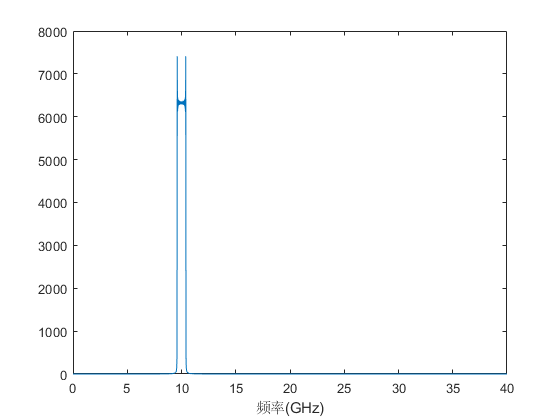


lfm_1 = exp(1j *2 * pi * (f0 * t + 0.5 * k * t.^2));
lfm_1 = lfm_1.';
tt = t.*k*50/1e9;
y = abs(fft(lfm_1));
plot(tt,y)
xlabel('频率(GHz)')
ylabel('')

## 第二种信号：线性负调频

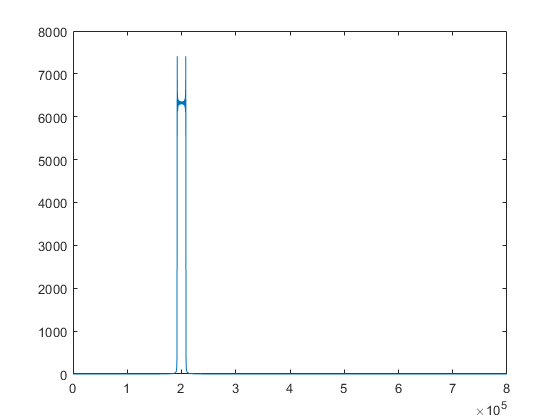

lfm_2 = exp(1j *2 * pi * (f1 * t - 0.5 * k * t.^2));
lfm_2 = lfm_2.';
plot(abs(fft(lfm_2)))

y = abs(fft(lfm_2));
plot(tt,y)
xlabel('频率(GHz)')
ylabel('')

## 第三种信号：正三次调频

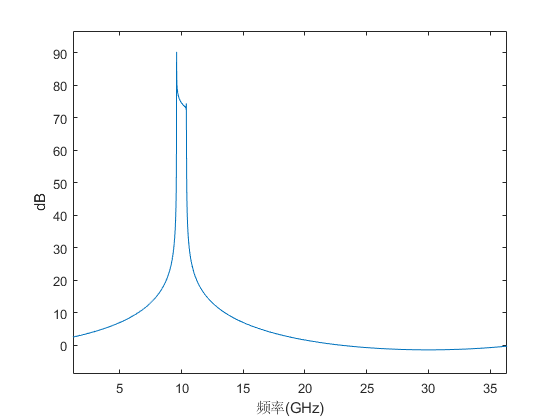

lfm_3 = exp(1j *2 * pi * (f0 * t + 1/3 * k/T * t.^3));
lfm_3 = lfm_3.';
y = 20*log10(abs(fft(lfm_3)));
plot(tt,y)
xlabel('频率(GHz)')
ylabel('dB')

## 第四种信号：负三次调频

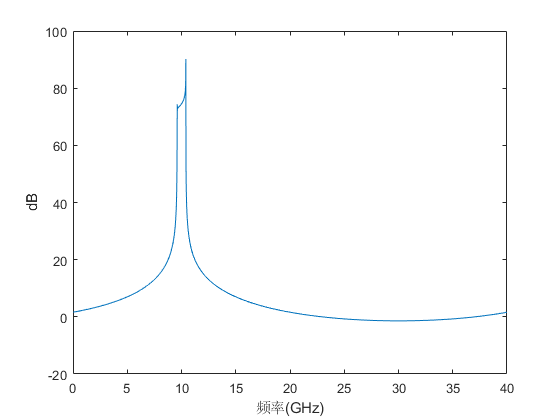

lfm_4 = exp(1j *2 * pi * (f1 * t - 1/3 * k/T * t.^3));
lfm_4 = lfm_4.';
y = 20*log10(abs(fft(lfm_4)));
plot(tt,y)
xlabel('频率(GHz)')
ylabel('dB')

## 第五种信号：正1.2次调频

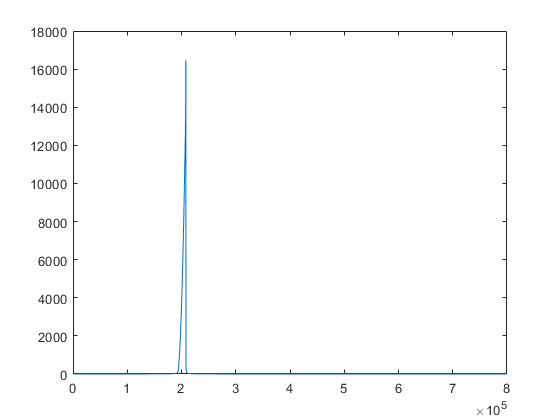

lfm_5 = exp(1j *2 * pi * (f0 * t + 1/1.2 * k * t.^1.2*(num/fs)^0.8));
lfm_5 = lfm_5.';
plot(abs(fft(lfm_5)))

## 第六种信号：负1.2次调频

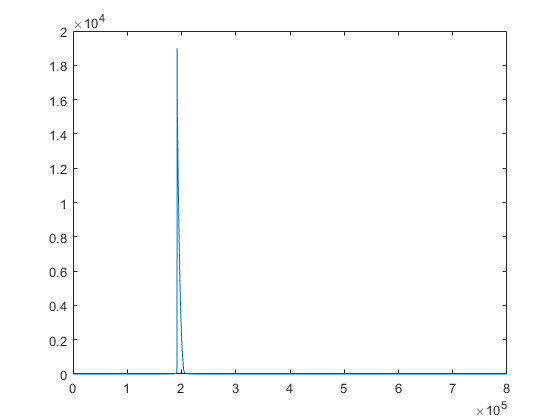

lfm_6 = exp(1j *2 * pi * (f1 * t - 1/1.15 * k * t.^1.15*(num/fs)^0.85));
lfm_6 = lfm_6.';
plot(abs(fft(lfm_6)))

## 第七种信号：余弦调频

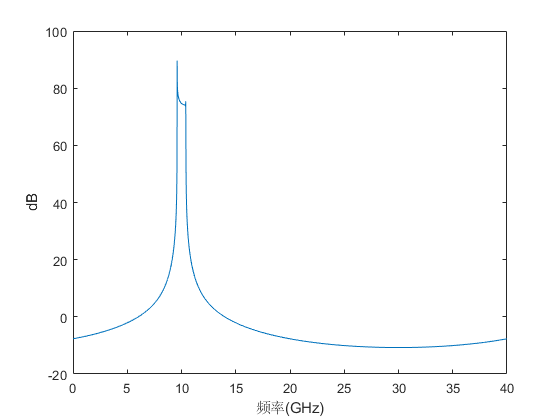

lfm_7 = exp(1j *2 * pi * (f1 * t +  (3.2/pi)*1e4*(cos(pi*k*t/16e8))));
lfm_7 = lfm_7.';
y = 20*log10(abs(fft(lfm_7)));
plot(tt,y)
xlabel('频率(GHz)')
ylabel('dB')

## 第八种信号：正弦调频

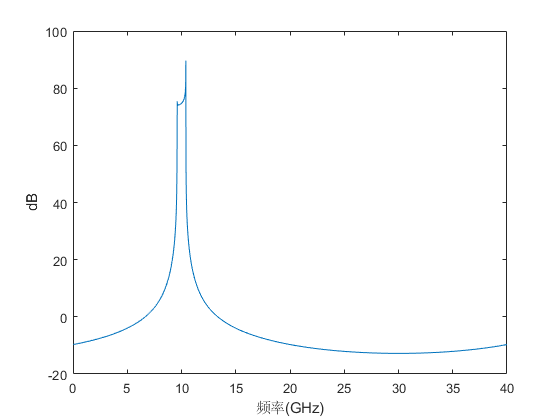

lfm_8 = exp(1j *2 * pi * (f0 * t + (3.2/pi)* 1e4*(sin(pi*k*t/16e8))));
lfm_8 = lfm_8.';
y = 20*log10(abs(fft(lfm_8)));
plot(tt,y)
xlabel('频率(GHz)')
ylabel('dB')


% Hw=conj(fft(lfm_8));
% Lfm_r=fft(lfm_7+lfm_8);
% Q=abs(fftshift(ifft(Lfm_r.*Hw)));
% figure(1)
% plot(20*log10(Q))


## 第九种信号：还在思考

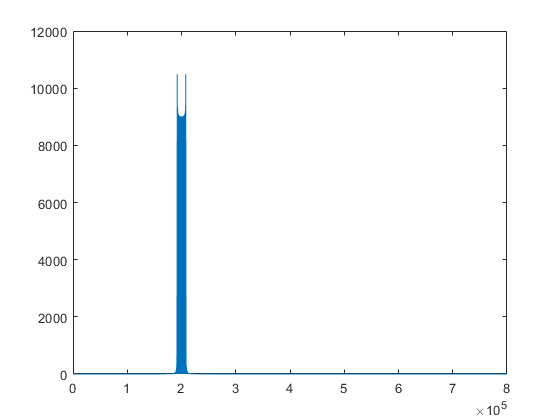

k2=k*2;
lfm_9=[exp(1j *2 * pi * (f0 * t1 + 0.5 * k2 * t1.^2)) exp(1j *2 * pi * (f0 * t1 + 0.5 * k2 * t1.^2))];
lfm_9=lfm_9.';
plot(abs(fft(lfm_9)))

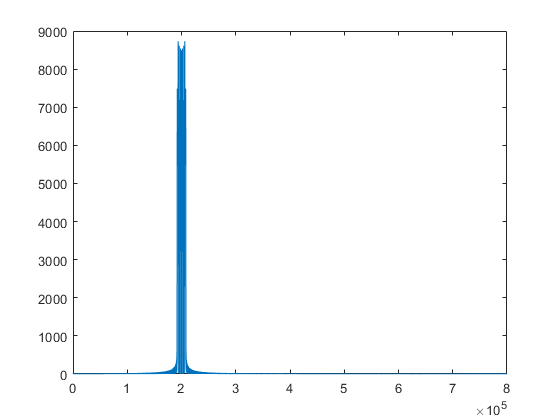

aa=t*num;
lfm_10 =[exp(1j *2 * pi * (f0 * t3 + 0.5* k * t3.^2))  exp(1j *2 * pi * (f0 * t4 + 0.5* k * t4.^2)+1j*pi) exp(1j *2 * pi * (f0 * t5 + 0.5* k * t5.^2)) exp(1j *2 * pi * (f0 * t6 + 0.5* k * t6.^2)+1j*pi) exp(1j *2 * pi * (f0 * t7 + 0.5* k * t7.^2)) exp(1j *2 * pi * (f0 * t8 + 0.5* k * t8.^2)+1j*pi) exp(1j *2 * pi * (f0 * t9 + 0.5* k * t9.^2)) exp(1j *2 * pi * (f0 * t10 + 0.5* k * t10.^2)+1j*pi)     ];
lfm_10=lfm_10.';
plot(abs(fft(lfm_10)))

## 用ln调制信号

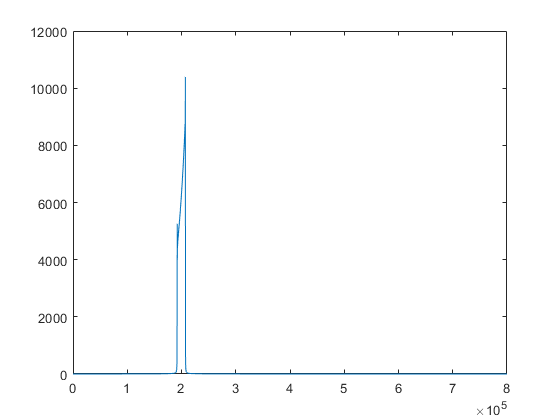


lfm_11 = exp(1j *2 * pi * (f0 * t + B/(exp(1)-1)*t.*log(1+(exp(1)-1)*(t./T))));
lfm_11 = lfm_11.';
plot(abs(fft(lfm_11)))

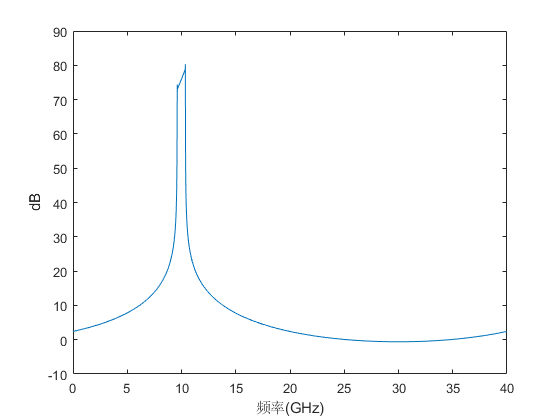

y = 20*log10(abs(fft(lfm_11)));
plot(tt,y)
xlabel('频率(GHz)')
ylabel('dB')

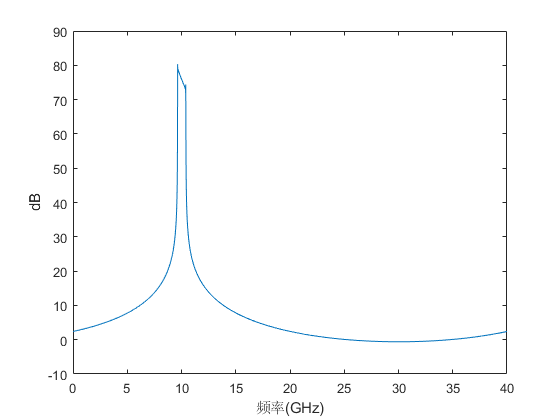



lfm_12 = exp(1j *2 * pi * (f1 * t - B/(exp(1)-1)*t.*log(1+(exp(1)-1)*(t./T))));
lfm_12 = lfm_12.';
y = 20*log10(abs(fft(lfm_12)));
plot(tt,y)
xlabel('频率(GHz)')
ylabel('dB')

## 用e调制信号

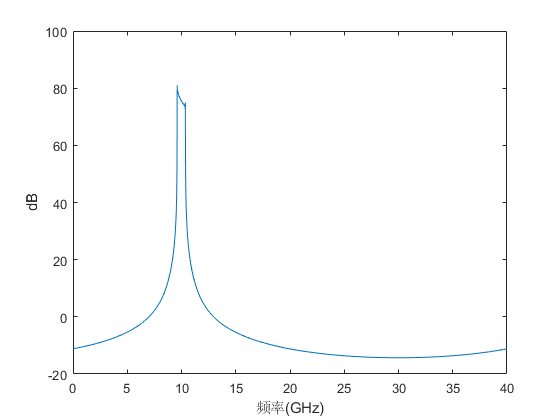

lfm_13 = exp(1j *2 * pi * (f0 * t + B/(expm(1))*t.*((exp(t./T)-1)/(expm(1)-1))));
lfm_13 = lfm_13.';
y = 20*log10(abs(fft(lfm_13)));
plot(tt,y)
xlabel('频率(GHz)')
ylabel('dB')

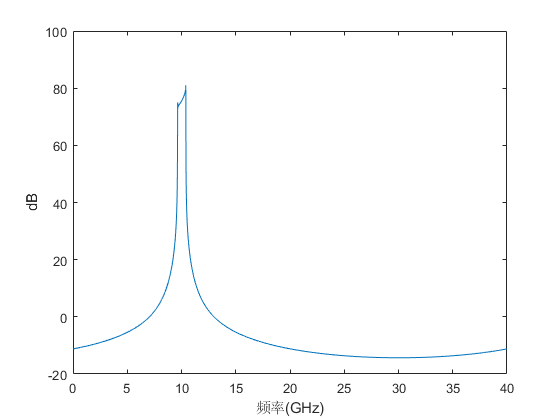



lfm_14 = exp(1j *2 * pi * (f1 * t - B/(expm(1))*t.*((exp(t./T)-1)/(expm(1)-1))));
lfm_14 = lfm_14.';
y = 20*log10(abs(fft(lfm_14)));
plot(tt,y)
xlabel('频率(GHz)')
ylabel('dB')

## 接着乱编

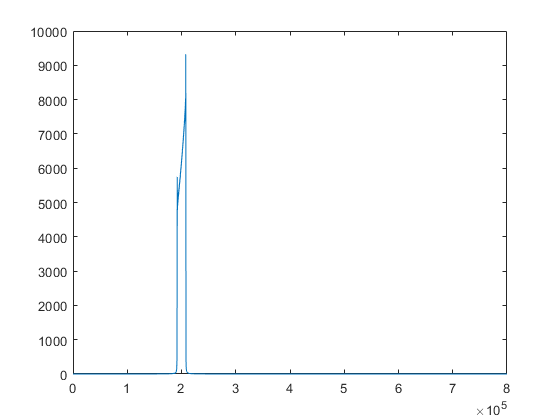

c=t./T;
lfm_15 = exp(1j *2 * pi * (f0 * t - B*t.*log(0.56) + B/(0.5+log(2))*t.*log(0.5+0.5*(t./T))));
lfm_15 = lfm_15.';
plot(abs(fft(lfm_15)))

% plot(abs(fft(lfm_15))+abs(fft(lfm_1)))


## 还是乱编

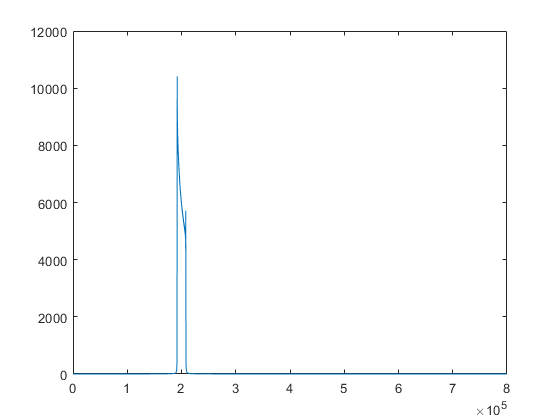

lfm_17 = exp(1j *2 * pi * (f0 * t  + B/2*T*(c.*2.^(c)/log(2)-2.^(c)/log(2)/log(2))));
lfm_17 = lfm_17.';
plot(abs(fft(lfm_17)))

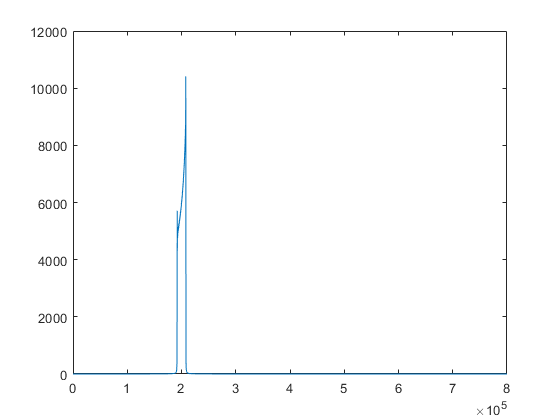


lfm_18 = exp(1j *2 * pi * (f1 * t - B/2*T*(c.*2.^(c)/log(2)-2.^(c)/log(2)/log(2))));
lfm_18 = lfm_18.';
plot(abs(fft(lfm_18)))

## 窗函数设计法

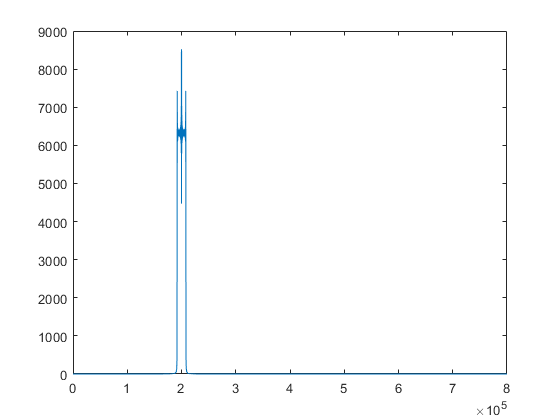

% N=1.6e4;
% n=1:1:1.6e4;
% Hanning=0.54-0.46*cos(2*pi*n./N).';
% plot(abs(Hanning))
% hanning=ifft(Hanning);
% plot(abs(fftshift(hanning)))

lfm_19=[exp(1j *2 * pi * (f10 * t1 - 0.5 * k * t1.^2)) exp(1j *2 * pi * (f0 * t1 + 0.5 * k * t1.^2))];
lfm_19 = lfm_19.';
plot(abs(fft(lfm_19)))

## svd

% lfm_3 = lfm_3.';
% lfm_4 = lfm_4.';
% lfm_7 = lfm_7.';
% lfm_8 = lfm_8.';
% lfm_11 = lfm_11.';
% lfm_12 = lfm_12.';
% lfm_13 = lfm_13.';
% lfm_14 = lfm_14.';
% AAA=[lfm_3;lfm_4;lfm_7;lfm_8;lfm_11;lfm_12;lfm_13;lfm_14];
% 
% [U,S,V] = svd(AAA,"econ");
% lfm_3=V(:,1);
% lfm_4=V(:,2);
% lfm_7=V(:,3);
% lfm_8=V(:,4);
% lfm_11=V(:,5);
% lfm_12=V(:,6);
% lfm_13=V(:,7);
% lfm_14=V(:,8);




## 尝试处理

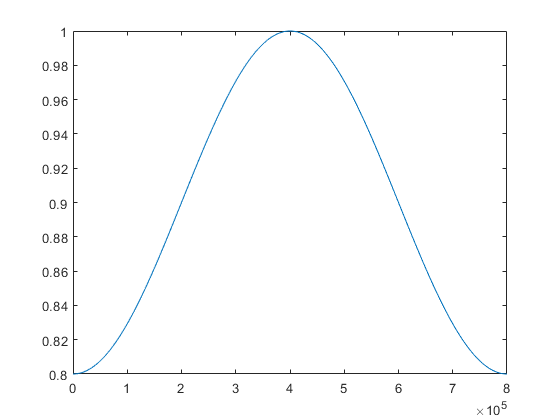

wn=0.54-0.46*cos(2*pi*t./T);
hn=0.9-0.1*cos(2*pi*t./T);
sjc=1-abs(1-2*t./T);
sinch=sin(pi*t./T);
ksc = kaiser(num,6);
plot(hn)

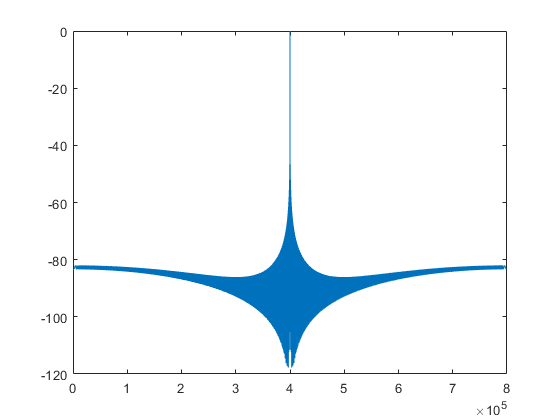

Hw=conj(fft(wn'.*(lfm_1)));
Lfm_r=fft(((lfm_1)')');
Q=abs(fftshift(ifft(Lfm_r.*Hw)));
% y = abs(fft(wn'.*lfm_1));
% plot(y)
% figure(1)
% subplot(4,2,1)
% plot(20*log10(abs(fftshift(ifft(conj(fft((lfm_14))).*fft(((lfm_14)')'))))/max(abs(fftshift(ifft(conj(fft(lfm_14))).*fft(((lfm_14)')'))))))
% title('加窗前单信号脉冲压缩')
% ylabel('dB')
% subplot(4,2,2)
% plot(20*log10(abs(fftshift(ifft(conj(fft(wn'.*(lfm_14))).*fft(((lfm_14)')'))))/max(abs(fftshift(ifft(conj(fft(wn'.*(lfm_14))).*fft(((lfm_14)')')))))))
% title('加窗后单信号脉冲压缩')
% ylabel('dB')
% subplot(4,2,3)
% plot(20*log10(abs(fftshift(ifft(conj(fft(wn'.*(lfm_14))).*fft(((lfm_14+lfm_3)')'))))/max(abs(fftshift(ifft(conj(fft(wn'.*(lfm_14))).*fft(((lfm_14+lfm_3)')')))))))
% title('用f7对（f7+f1）信号做脉冲压缩')
% ylabel('dB')
% subplot(4,2,4)
% plot(20*log10(abs(fftshift(ifft(conj(fft(wn'.*(lfm_14))).*fft(((lfm_14+lfm_4)')'))))/max(abs(fftshift(ifft(conj(fft(wn'.*(lfm_14))).*fft(((lfm_14+lfm_4)')')))))))
% title('用f7对（f7+f2）信号做脉冲压缩')
% ylabel('dB')
% subplot(4,2,5)
% plot(20*log10(abs(fftshift(ifft(conj(fft(wn'.*(lfm_14))).*fft(((lfm_14+lfm_7)')'))))/max(abs(fftshift(ifft(conj(fft(wn'.*(lfm_14))).*fft(((lfm_14+lfm_7)')')))))))
% title('用f7对（f7+f3）信号做脉冲压缩')
% ylabel('dB')
% subplot(4,2,6)
% plot(20*log10(abs(fftshift(ifft(conj(fft(wn'.*(lfm_14))).*fft(((lfm_14+lfm_11)')'))))/max(abs(fftshift(ifft(conj(fft(wn'.*(lfm_14))).*fft(((lfm_14+lfm_11)')')))))))
% title('用f7对（f7+f4）信号做脉冲压缩')
% ylabel('dB')
% subplot(4,2,7)
% plot(20*log10(abs(fftshift(ifft(conj(fft(wn'.*(lfm_14))).*fft(((lfm_14+lfm_12)')'))))/max(abs(fftshift(ifft(conj(fft(wn'.*(lfm_14))).*fft(((lfm_14+lfm_12)')')))))))
% title('用f7对（f7+f5）信号做脉冲压缩')
% ylabel('dB')
% subplot(4,2,8)
% plot(20*log10(abs(fftshift(ifft(conj(fft(wn'.*(lfm_14))).*fft(((lfm_14+lfm_13)')'))))/max(abs(fftshift(ifft(conj(fft(wn'.*(lfm_14))).*fft(((lfm_14+lfm_13)')')))))))
% title('用f7对（f7+f6）信号做脉冲压缩')
% ylabel('dB')

figure(2)
plot(20*log10(Q/max(Q)))

% CQ=ifft(Lfm_r.*Hw);
% DQ=fft(angle(CQ));
% EQ=Lfm_r.*Hw;
% FQ=conj(DQ).*EQ;
% GQ=ifft(FQ);
% plot(20*log10(abs(fftshift(GQ))/max(abs(GQ))))

% Lfm_r2=fft(lfm_3);
% AA=Lfm_r2.*Hw;
% Qw=abs(fftshift(ifft(AA)));
% figure(2)
% plot(20*log10(Qw/max(Qw)))


% figure("name",'STFT_lfm_r2','NumberTitle','off');
% spectrogram(lfm_1+lfm_13+lfm_11,window,overLap,nfft,fs);  
% figure("name",'STFT_lfm_r2','NumberTitle','off');
% spectrogram(Q,window,overLap,nfft,fs);  
% 
% cw= abs(fft((Lfm_r.*Hw)));
% qw=conj(fft((ifft(Lfm_r.*Hw))));
% plot(20*log10(abs(fftshift(ifft((cw.*qw))))))